clear
clc
close all

%% Change directory
% Get the full path of the currently running script
if isdeployed
    % If the code is deployed, use the built-in method
    scriptFullPath = mfilename('fullpath');
else
    % If running in the MATLAB environment, use the editor API
    scriptFullPath = matlab.desktop.editor.getActiveFilename;
end

% Extract the directory part of the path
[scriptDir, ~, ~] = fileparts(scriptFullPath);

% Change the current directory to the script's directory
cd(scriptDir);

% Display the current directory to confirm the change
disp(['Current directory changed to: ', scriptDir]);

Current directory changed to: C:\Users\giaco\Git_Repositories\Semester_Thesis_1\Data\State Space


A = table2array(readtable('Data/State Space/A.csv'));
B = table2array(readtable('Data/State Space/B.csv'));
h = table2array(readtable('Data/State Space/h.csv'));
C = table2array(readtable('Data/State Space/C.csv'));
D = table2array(readtable('Data/State Space/D.csv'));
l = table2array(readtable('Data/State Space/l.csv'));
k = table2array(readtable('Data/State Space/K.csv'));

sys = ss(A, B, C, D);
P = tf(sys);

% Discretization
Ts = 1;
sys_d = c2d(sys, Ts);

A_d = sys_d.A;
B_d = sys_d.B;
C_d = sys_d.C;
D_d = sys_d.D;

Controllability

Co = ctrb(sys);
unco = length(A) - rank(Co)

unco = 0


Co_d = ctrb(sys_d);
unco_d = length(A_d) - rank(Co_d)

unco_d = 0

Observability

Ob = obsv(sys);
unobsv = length(A) - rank(Ob)

unobsv = 0


Ob_d = obsv(sys_d);
unobsv_d = length(A_d) - rank(Ob_d)

unobsv_d = 0

Stability

[V, eig_val] = eigs(A);
isstable(sys)

ans = logical
   0


eigvec1_op = V(2:end, 2);
eigvec2_op = V(2:end, 3);
slope1_op = eigvec1_op(2) / eigvec1_op(1);
slope2_op = eigvec2_op(2) / eigvec2_op(1);

[V_d, eig_val_d] = eigs(A_d);
isstable(sys_d)

ans = logical
   0


LQR

Q = [0, 0, 0;
     0, 1, 0;
     0, 0, 0];
R = [1/3,0;
     0, 1];

[K, S, P] = lqr(A, B, Q, R);
A_cl = A - B * K;
[V_cl, eig_val] = eigs(A_cl);
eigvec1_cl = V_cl(2:end, 2);
eigvec2_cl = V_cl(2:end, 3);
slope1_cl = eigvec1_cl(2) / eigvec1_cl(1);
slope2_cl = eigvec2_cl(2) / eigvec2_cl(1);

[K_d, S_d, P_d] = dlqr(A_d, B_d, Q, R);
A_cl_d = A_d - B_d * K_d;

RGA

% RGA_matrix = P .* inv(P');
% RGA_freq = evalfr(RGA_matrix, 0)

Phase portraits

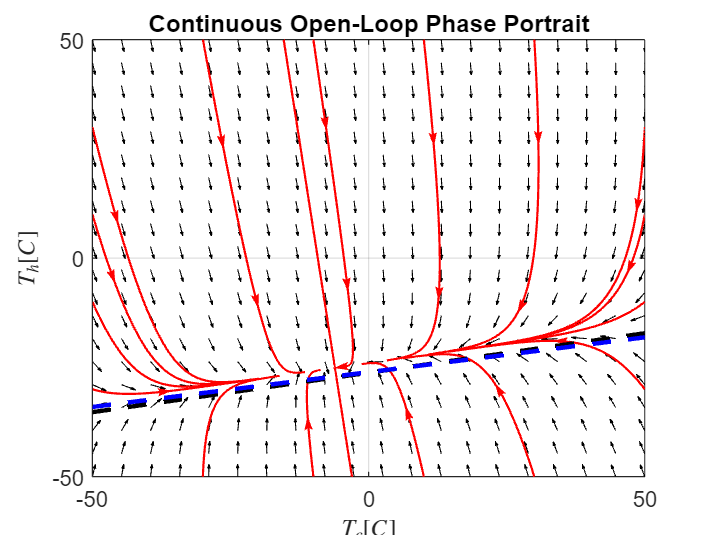

A23 = A(2:3, 2:3);
odefun_open = @(t, x) [A23(1,1)*(x(1) - 273.15) + A23(1,2)*(x(2) - 273.15) + h(2); %-0.002827147021890*(x - 273.15) + 0.002237389329821*(y - 273.15) + -0.122129663825035
                       A23(2,1)*(x(1) - 273.15) + A23(2,2)*(x(2) - 273.15) + h(3)]; %0.003269244683906*(x - 273.15) -0.020527653396130*(y - 273.15) + -5.209770202636719
A23_d = A_d(2:3, 2:3);
odefun_open_d = @(t, x) [A23_d(1,1)*(x(1) - 273.15) + A23_d(1,2)*(x(2) - 273.15) + h(2); %
                         A23_d(2,1)*(x(1) - 273.15) + A23_d(2,2)*(x(2) - 273.15) + h(3)]; %

A_cl23 = A_cl(2:3, 2:3);
odefun_closed = @(t, x) [A_cl23(1,1)*(x(1) - 273.15) + A_cl23(1,2)*(x(2) - 273.15) + h(2); %-0.177740807921086*(x - 273.15) + 5.008616595525719e-04*(y - 273.15) + -0.122129663825035
                         A_cl23(2,1)*(x(1) - 273.15) + A_cl23(2,2)*(x(2) - 273.15) + h(3)]; %-0.314244193898858*(x - 273.15) -0.044649544708827*(y - 273.15) + -5.209770202636719
A_cl23_d = A_cl_d(2:3, 2:3);
odefun_closed_d = @(t, x) [A_cl23_d(1,1)*(x(1) - 273.15) + A_cl23_d(1,2)*(x(2) - 273.15) + h(2); %
                           A_cl23_d(2,1)*(x(1) - 273.15) + A_cl23_d(2,2)*(x(2) - 273.15) + h(3)]; %

% Parameters
tspan_op = 400;
tspan_cl = 50;
Tc_limits_op = [-50, 50];
Th_limits_op = [-50, 50];
Tc_limits_op_d = [-200, 0];
Th_limits_op_d = [-200, 0];
Tc_limits_cl = [250, 300];
Th_limits_cl = [100, 200];

% Open-Loop Phase Portrait
figure;
plotpp(odefun_open, 'tspan', tspan_op, 'xlim', Tc_limits_op, 'ylim', Th_limits_op, 'quivercolor', 'k', 'linecolor', 'r')
hold on
plot(Tc_limits_op, slope1_op*(Tc_limits_op-6.095) -25.115, '--k', 'LineWidth', 2);
plot(Tc_limits_op, slope2_op*(Tc_limits_op-6.095) -25.115, '--b', 'LineWidth', 2);
title('Continuous Open-Loop Phase Portrait');
xlabel('$T_c [C]$', Interpreter='latex')
ylabel('$T_h [C]$', Interpreter='latex')
hold off

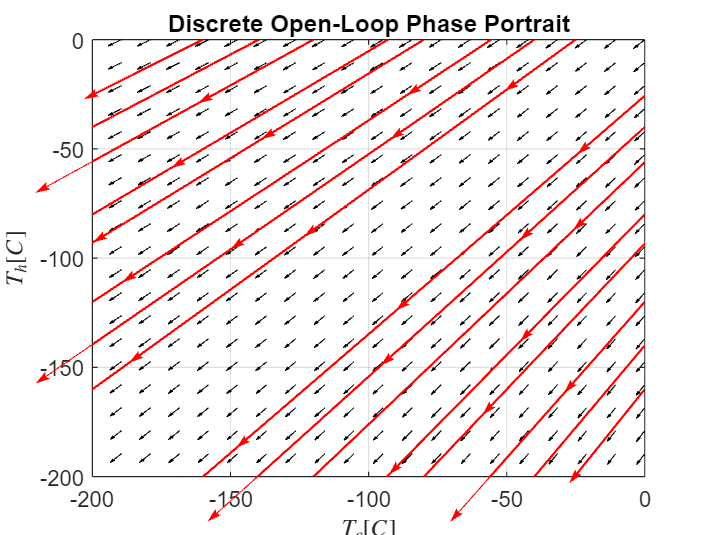


figure;
plotpp(odefun_open_d, 'tspan', tspan_op, 'xlim', Tc_limits_op_d, 'ylim', Th_limits_op_d, 'quivercolor', 'k', 'linecolor', 'r')
title('Discrete Open-Loop Phase Portrait');
xlabel('$T_c [C]$', Interpreter='latex')
ylabel('$T_h [C]$', Interpreter='latex')

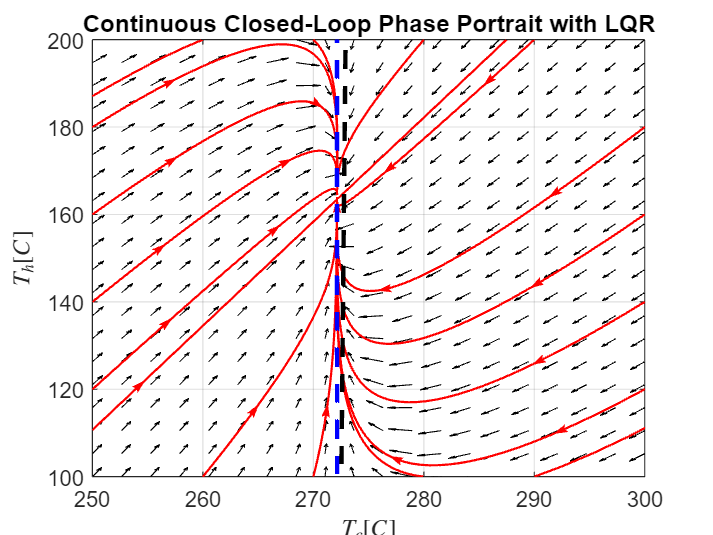


% Closed-Loop Phase Portrait
figure;
plotpp(odefun_closed, 'tspan', tspan_cl, 'xlim', Tc_limits_cl, 'ylim', Th_limits_cl, 'quivercolor', 'k', 'linecolor', 'r')
hold on
plot(Tc_limits_cl, slope1_cl*(Tc_limits_cl-272.154), '--k', 'LineWidth', 2);
plot(Tc_limits_cl, slope2_cl*(Tc_limits_cl-272.154), '--b', 'LineWidth', 2);
title('Continuous Closed-Loop Phase Portrait with LQR');
xlabel('$T_c [C]$', Interpreter='latex')
ylabel('$T_h [C]$', Interpreter='latex')

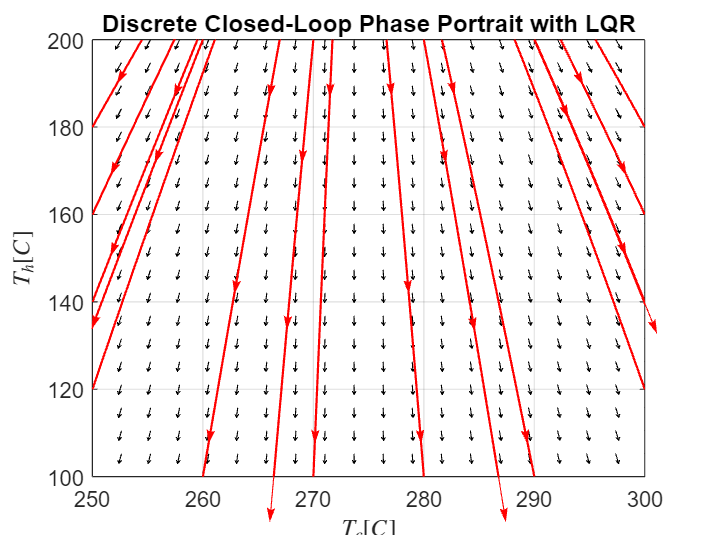


figure;
plotpp(odefun_closed_d, 'tspan', tspan_cl, 'xlim', Tc_limits_cl, 'ylim', Th_limits_cl, 'quivercolor', 'k', 'linecolor', 'r')
title('Discrete Closed-Loop Phase Portrait with LQR');
xlabel('$T_c [C]$', Interpreter='latex')
ylabel('$T_h [C]$', Interpreter='latex')